# Importing 3D Images

You've seen how to import a series of images as a 3D volume using the Volume Viewer app. You've also performed custom segmentations using the Volume Segmenter app. The Volume Viewer and Segmenter apps are useful tools to gain familiarity with your 3D images and perform common operations.

However, if you need to process many 3D images or perform highly customized operations, it might be more useful to analyze your volumes with code.

In this reading, you'll learn how to import, create, and view 3D objects in your scripts.

## Common Medical Image Formats

Many medical scanners use file types specific to medical imaging. In addition to common image file formats, MATLAB also supports many medical imaging formats such as: 

- DICOM ("Digital Imaging and Communications in Medicine")

- IMA ("Image", a disk image very similar to DICOM)

- NIfTI ("Neuroimaging Informatics Technology Initiative")

- Analyze 7.5

Let's take a closer look at the images we used in the "Analyzing 3D Images" video:

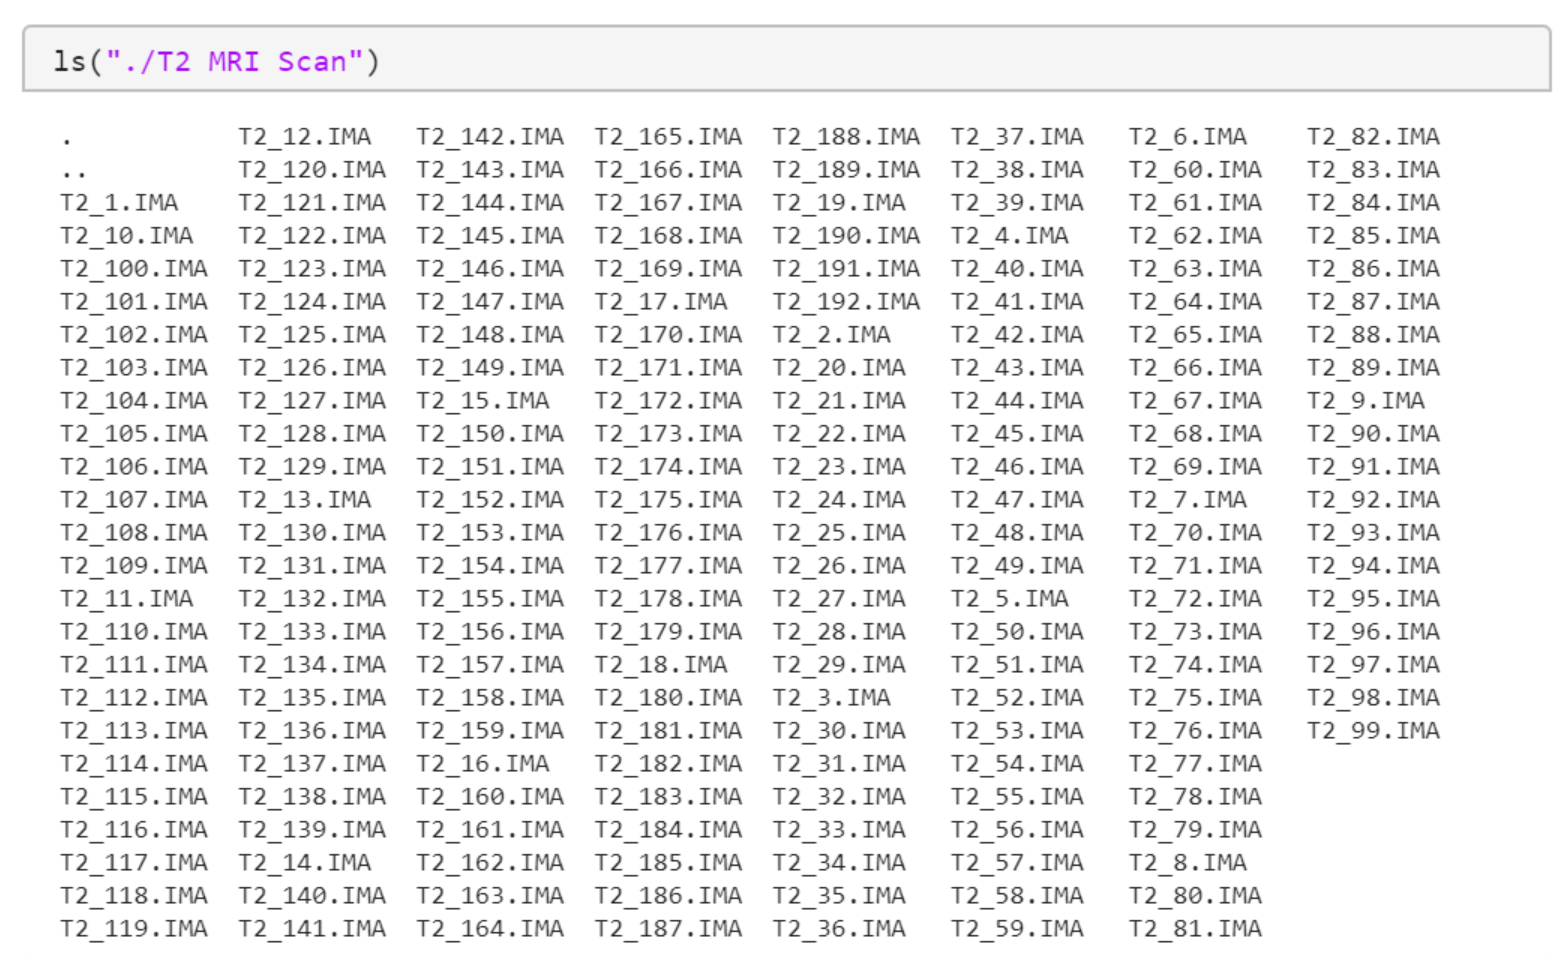

We see that our 3-dimmensional brain scan is composed many individual IMA files.

### Reading Medical Images

Many of the functions we've used in the image processing toolbox have equivalents for DICOM and IMA files.

brain76Meta = dicominfo("T2_76.IMA")    % Display meta data for DICOM/IMA image

brain76Meta = struct with fields:
                             Filename: 'C:\Users\backupadmin\Documents\ImageProcessingCoursera\Image Processing for Engineering and Science\Data\MathWorks Images\T2 MRI Scan\T2_76.IMA'
                          FileModDate: '04-Jan-2022 17:37:10'
                             FileSize: 133222
                               Format: 'DICOM'
                        FormatVersion: 3
                                Width: 256
                               Height: 256
                             BitDepth: 16
                            ColorType: 'grayscale'
       FileMetaInformationGroupLength: 210
           FileMetaInformationVersion: [2×1 uint8]
              MediaStorageSOPClassUID: '1.2.840.10008.5.1.4.1.1.4'
           MediaStorageSOPInstanceUID: '1.3.6.1.4.1.9590.100.1.2.383125523312033013016153209983059058139'
                    TransferSyntaxUID: '1.2.840.10008.1.2.1'
               ImplementationClassUID: '1.3.6.1.4.1.9590.100.1.3.100.9.4'
    

imgBrain76 = dicomread("T2_76.IMA");     % Read in single image from 3D volume

Similar commands also exist for [NifTI](https://www.mathworks.com/help/images/ref/niftiread.html) and [Analyze 7.5](https://www.mathworks.com/help/images/ref/analyze75read.html#bvie7ob-1) files.

Once we've read in the medical image with the appropriate command, we can use the tools we've already used in this course. Use `imshow` to display `imgBrain76`:

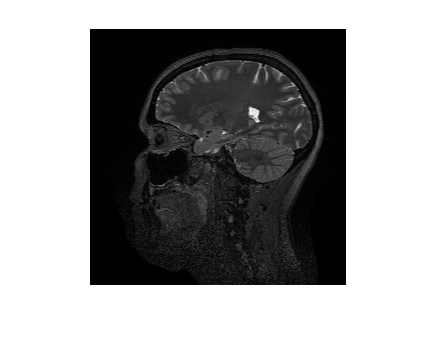

imshow(imgBrain76,[])

If you're having trouble seeing the image, you may want to review [Viewing Meta-Data and non-uint8 Images](https://www.coursera.org/learn/ip-matlab/supplement/h0HzU/viewing-meta-data-and-non-uint8-images).

## 3D Images as a Series of Images

Volumes are a series of images organized over x, y, and z spatial planes. One of the most intuitive ways to visualize this is to look at a series of 2D images taken at regular points over the third spatial plane.

Read in `T2_71.IMA` through `T2_75.IMA` and display them to get an idea of what the volume looks like in a section of the Y-Z (left to right, or "sagittal") plane.

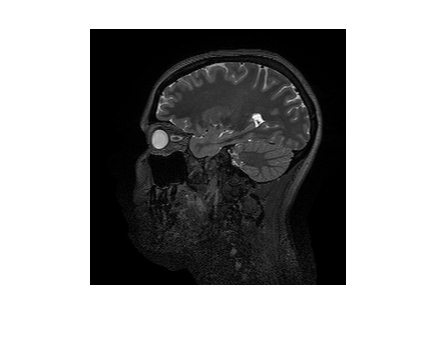

imgBrain71 = dicomread("T2_71.IMA"); 
imgBrain72 = dicomread("T2_72.IMA"); 
imgBrain73 = dicomread("T2_73.IMA"); 
imgBrain74 = dicomread("T2_74.IMA"); 
imgBrain75 = dicomread("T2_75.IMA"); 
imshow(imgBrain71,[])
imshow(imgBrain72,[])

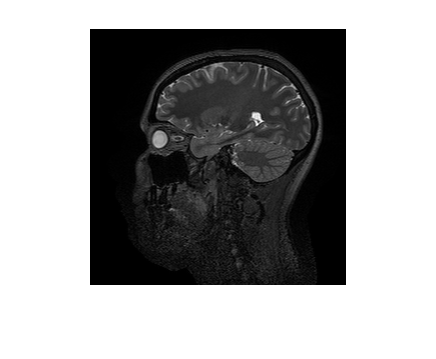

imshow(imgBrain73,[])

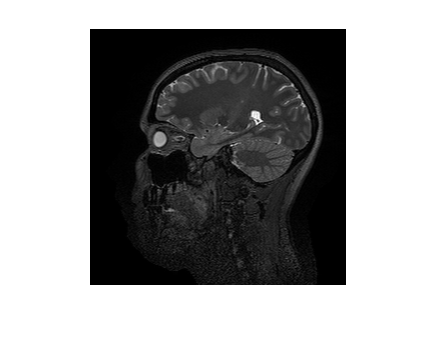

imshow(imgBrain74,[])

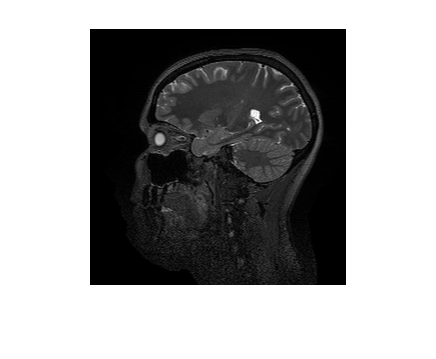

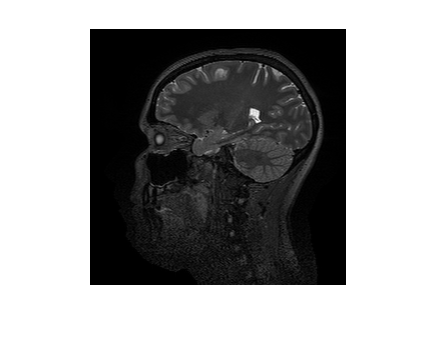

imshow(imgBrain75,[])

Viewing volumes by looking at a series of images in one plane, or slices, is very popular with radiologists.

## 3D Images as Volumes

While viewing volumes as series of 2D images makes it easy to visualize 3D objects on the 2D surface of your screen, it also has drawbacks. Consider this image of a single slice of a stained tumor:

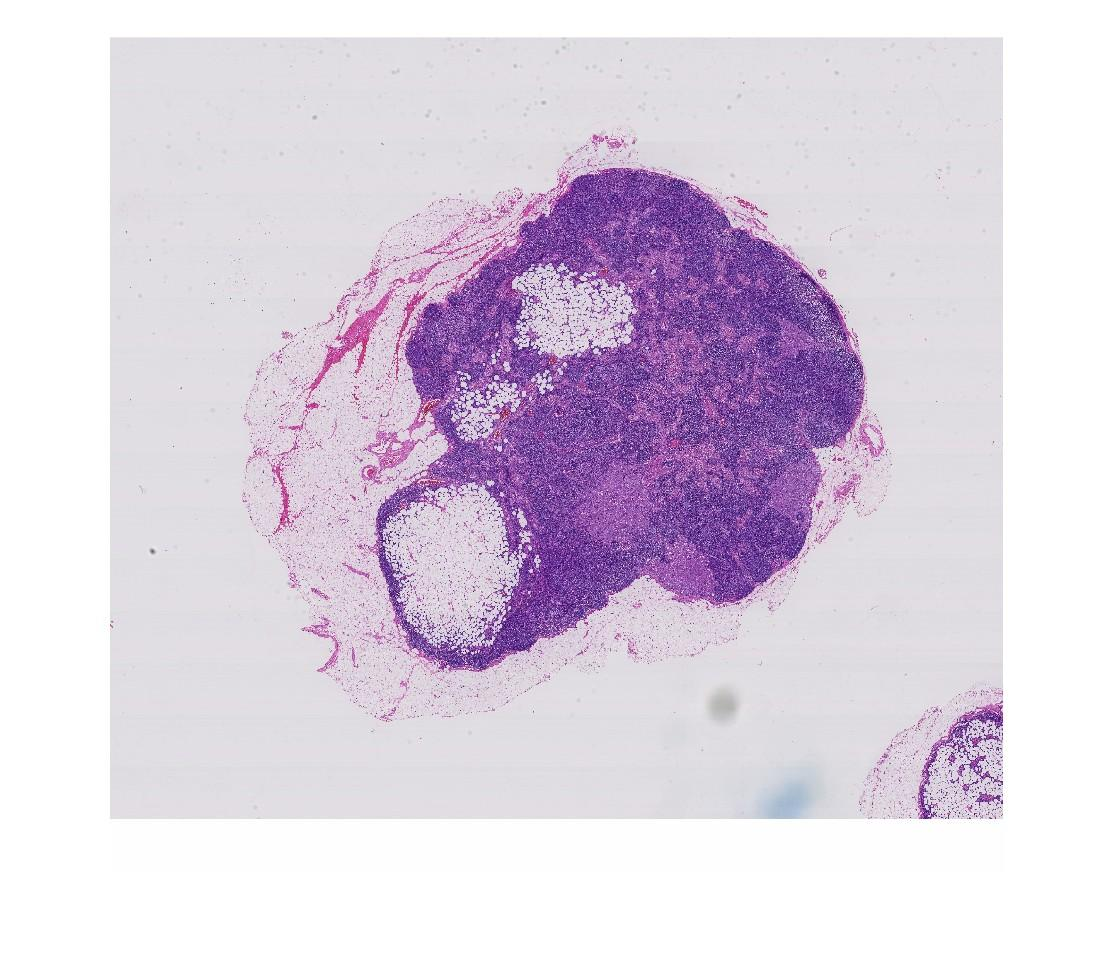

We can see the size of the removed tumor at a single cross-section, but usually we would want to see the whole tumor before it's removed in order to make treatment decisions.

### Creating a Volume Object

Creating a volume allows us to see images on our screen with an approximation of the depth we see in the real world. It also allows us to calculate useful parameters such as volume and surface area.

As with our /`'T2 MRI Scan'` directory, 2D slices of a volume will usually be saved with sequential names. This enables MATLAB to assemble the images from a folder in the correct order to create a volume. 

Before you can create the volume, you first need to set the path to the `'T2 MRI Scan'` folder provided with the course files:

mrDir = uigetdir

Now you are ready to load the volume:

vol = dicomreadVolume(fullfile(mrDir));

mrDir = 'C:\Users\backupadmin\Documents\ImageProcessingCoursera\Image Processing for Engineering and Science\Data\MathWorks Images\T2 MRI Scan'

#### Removing extra dimensions

You might notice something strange about our new, 3D volume:

size(vol)

Why does our 3D volume have 4 dimensions? And why does our 3rd dimension have a length of `1`? Because our images, like many medical images, are grayscale, the "color" dimension of our volume is empty, leading to a "singleton" dimension. Let's remove it and check the size again:

vol = squeeze(vol);
size(vol)

ans =    256   256     1   192


That makes a lot more sense!

### Viewing a Volume Object

Now we're finally ready to see our volume:

volshow(vol);

ans =    256   256   192


Now that is an impressive head. Let's check out some individual slices:

figure
sliceViewer(vol)

You can scroll through slices from different planes using the `SliceDirection` parameter:

sliceViewer(vol,"SliceDirection","X")

Keep in mind, if your imported image isn't oriented correctly, the slice view direction might not correspond to the plane you expect. Try viewing the volume in different slice planes:

sliceViewer(vol,"SliceDirection","Y")

threshValues = multithresh(vol,4)

ans =   sliceViewer with properties:

             SliceDirection: [0 0 1]
                SliceNumber: 97
                     Parent: [1×1 Panel]
                   Colormap: [256×3 double]
               DisplayRange: [0 740]
               ScaleFactors: [1 1 1]
    DisplayRangeInteraction: 'on'


labels = imquantize(vol,threshValues);
sliceViewer(labels,"SliceDirection","Y")

ans =   sliceViewer with properties:

             SliceDirection: 'X'
                SliceNumber: 97
                     Parent: [1×1 Panel]
                   Colormap: [256×3 double]
               DisplayRange: [0 740]
               ScaleFactors: [1 1 1]
    DisplayRangeInteraction: 'on'


ans =   sliceViewer with properties:

             SliceDirection: 'Y'
                SliceNumber: 97
                     Parent: [1×1 Panel]
                   Colormap: [256×3 double]
               DisplayRange: [0 740]
               ScaleFactors: [1 1 1]
    DisplayRangeInteraction: 'on'


threshValues = 1×4 uint16 row vector
    52   136   354   725


ans =   sliceViewer with properties:

             SliceDirection: 'Y'
                SliceNumber: 97
                     Parent: [1×1 Panel]
                   Colormap: [256×3 double]
               DisplayRange: [1 5]
               ScaleFactors: [1 1 1]
    DisplayRangeInteraction: 'on'


Once you have a volume object, you can view it, perform manual calculations, or import it from the workspace into the Volume Segmenter app.

*Copyright 2022 The MathWorks, Inc.*